# Pricing Swaps with Discount Pricer

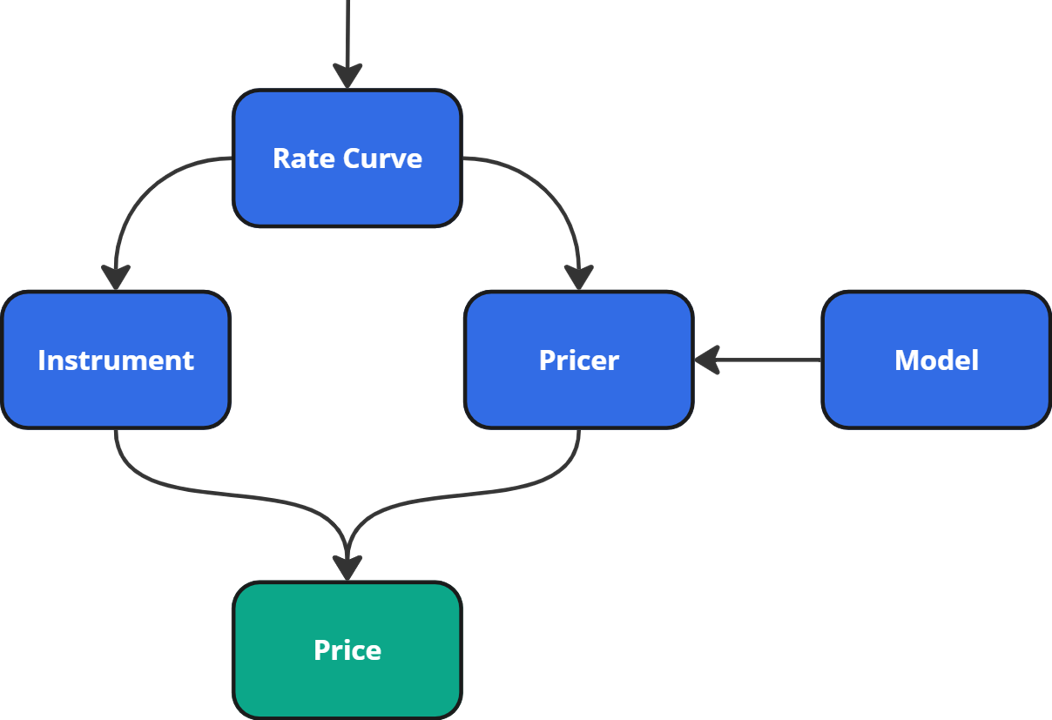

## Price Swap using Financial Instruments Toolbox

% Swap Information
Settle = datetime("2019-09-15", "InputFormat", "uuuu-MM-dd");
MaturityDate = datetime("2024-09-15", "InputFormat", "uuuu-MM-dd");
Leg1Type = "float";
Leg1Rate = 0.022; 
Leg2Type = "fixed";
Leg2Rate = 0.019; 

% Rate Curve
Type = "zero";
ZeroTimes = [calmonths(6) calyears([1 2 3 4 5 7 10 20 30])]';
monthRate6 = 0.0052;
monthRate12 = 0.0055;
monthRate24 = 0.0061;
monthRate36 = 0.0073;
monthRate48 = 0.0094;
monthRate60 = 0.0119;
monthRate72 = 0.0168;
monthRate120 = 0.0222;
monthRate240 = 0.0293;
monthRate360 = 0.307;
ZeroRates = [monthRate6...
    monthRate12...
    monthRate24...
    monthRate36...
    monthRate48...
    monthRate60...
    monthRate72...
    monthRate120...
    monthRate240...
    monthRate360]';
ZeroDates = Settle + ZeroTimes;
myRC = ratecurve(Type,Settle,ZeroDates,ZeroRates);

% Swap
Swap = fininstrument("Swap",'Maturity',MaturityDate,'LegRate',[Leg1Rate Leg2Rate],'LegType',[Leg1Type,Leg2Type],'ProjectionCurve',myRC,'Name',"swap_instrument");

% Swap Pricer
Pricer = finpricer("Discount", 'DiscountCurve',myRC);
[Price, outPR] = price(Pricer,Swap,"all");
outPR.Results

ans = 1x2 table
    Price       DV01   
    ______    _________

    7.2279    -0.046631


## Verify Swap Model

CurveType = "zero"; % Specify the type of rate curve
Settle = datetime("2019-09-15", "InputFormat", "uuuu-MM-dd");
ZeroTimesMonths = [1     3     6    12    24    36    60    84   120   240   360]';
ZeroRates = [0.0546    0.0552    0.0539    0.0517    0.0481    0.0457    0.0441    0.0440    0.0439    0.0462    0.0453]';
MaturityDate = datetime("2024-09-15", "InputFormat", "uuuu-MM-dd");
Leg1Type = "float";
Leg1Rate = 0.076;
Leg2Type = "fixed";
Leg2Rate = 0.03;

[Price, Results] = priceSwapDiscount(CurveType, Settle, ZeroTimesMonths, ZeroRates, MaturityDate, Leg1Type, Leg1Rate, Leg2Type, Leg2Rate)

Price = 40.0732

Results = struct with fields:
    Price: 40.0732
     DV01: -0.0347
